## Example1

clear all
s=tf('s');

G=10*(s+3)/(s*(s+2)*(s^2+s+2))

G =
 
          10 s + 30
  -------------------------
  s^4 + 3 s^3 + 4 s^2 + 4 s
 
연속시간 전달 함수입니다.



clear all
s=tf('s');

G=(s+1)/(s-1)^2

G =
 
      s + 1
  -------------
  s^2 - 2 s + 1
 
연속시간 전달 함수입니다.



## Plot from freqeuncy response

w=logspace(-2,2,100) % log scale 주파수 범위 생성

w =     0.0100    0.0110    0.0120    0.0132    0.0145    0.0159    0.0175    0.0192    0.0210    0.0231    0.0254    0.0278    0.0305    0.0335    0.0368    0.0404    0.0443    0.0486    0.0534    0.0586    0.0643    0.0705    0.0774    0.0850    0.0933    0.1024    0.1123    0.1233    0.1353    0.1485    0.1630    0.1789    0.1963    0.2154    0.2364    0.2595    0.2848    0.3126    0.3430    0.3765    0.4132    0.4535    0.4977    0.5462    0.5995    0.6579    0.7221    0.7925    0.8697    0.9545


H=freqresp(G,w) % 주파수 범위를 근으로 취하는 전달함수 응답

H = H(:,:,1) =

   0.9995 + 0.0300i


H(:,:,2) =

   0.9994 + 0.0329i


H(:,:,3) =

   0.9993 + 0.0361i


H(:,:,4) =

   0.9991 + 0.0396i


H(:,:,5) =

   0.9989 + 0.0435i


H(:,:,6) =

   0.9987 + 0.0477i


H(:,:,7) =

   0.9985 + 0.0524i


H(:,:,8) =

   0.9982 + 0.0575i


H(:,:,9) =

   0.9978 + 0.0631i


H(:,:,10) =

   0.9973 + 0.0692i


H(:,:,11) =

   0.9968 + 0.0759i


H(:,:,12) =

   0.9961 + 0.0833i


H(:,:,13) =

   0.9953 + 0.0914i


H(:,:,14) =

   0.9944 + 0.1003i


H(:,:,15) =

   0.9933 + 0.1100i


H(:,:,16) =

   0.9919 + 0.1207i


H(:,:,17) =

   0.9902 + 0.1323i


H(:,:,18) =

   0.9882 + 0.1451i


H(:,:,19) =

   0.9858 + 0.1590i


H(:,:,20) =

   0.9830 + 0.1743i


H(:,:,21) =

   0.9795 + 0.1910i


H(:,:,22) =

   0.9753 + 0.2092i


H(:,:,23) =

   0.9703 + 0.2291i


H(:,:,24) =

   0.9644 + 0.2507i


H(:,:,25) =

   0.9572 + 0.2742i


H(:,:,26) =

   0.9486 + 0.2997i


H(:,:,27) =

   0.9383 + 0.3273i


H(:,:,28) =

   0.9260 + 0.3570i


H(:,:,29) =

   0.9114 + 

GW=reshape(H,100,1) % 전달함수 응답 간단 출력

GW =    0.9995 + 0.0300i
   0.9994 + 0.0329i
   0.9993 + 0.0361i
   0.9991 + 0.0396i
   0.9989 + 0.0435i
   0.9987 + 0.0477i
   0.9985 + 0.0524i
   0.9982 + 0.0575i
   0.9978 + 0.0631i
   0.9973 + 0.0692i


Mag=abs(GW)

Mag =     1.0000
    0.9999
    0.9999
    0.9999
    0.9999
    0.9999
    0.9998
    0.9998
    0.9998
    0.9997


Phase=angle(GW)

Phase =     0.0300
    0.0329
    0.0361
    0.0397
    0.0435
    0.0478
    0.0524
    0.0575
    0.0631
    0.0693


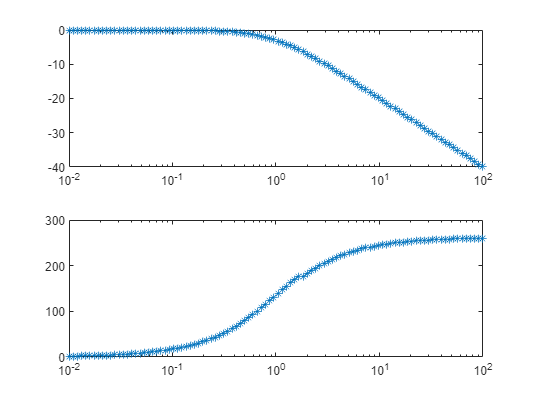

figure
subplot(211)
semilogx(w,20*log10(Mag),'*')
subplot(212)
semilogx(w,unwrap(rad2deg(Phase),180),'*')

## Bode Diagram

G1=tf(10*3/4)

G1 =
 
  7.5
 
정적 이득입니다.



G2=1/s

G2 =
 
  1
  -
  s
 
연속시간 전달 함수입니다.



G3=(s+3)/3

G3 =
 
  s + 3
  -----
    3
 
연속시간 전달 함수입니다.



G4=2/(s+2)

G4 =
 
    2
  -----
  s + 2
 
연속시간 전달 함수입니다.



G5=2/(s^2+s+2)

G5 =
 
       2
  -----------
  s^2 + s + 2
 
연속시간 전달 함수입니다.



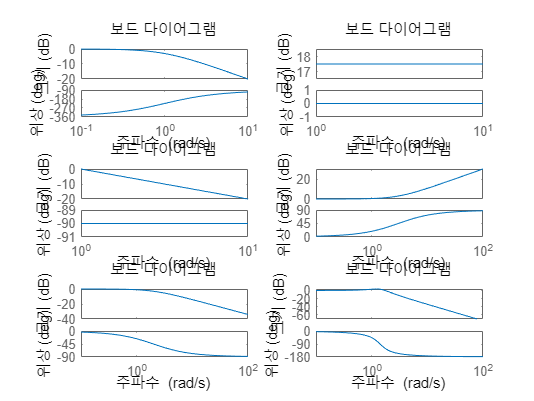


figure;
subplot(3,2,1); bode(G)
subplot(3,2,2); bode(G1)
subplot(3,2,3); bode(G2)
subplot(3,2,4); bode(G3)
subplot(3,2,5); bode(G4)
subplot(3,2,6); bode(G5)

## Characteristics

dcgain(G)

ans = 1

bandwidth(G)

ans = 0.9976

dcgain(G4)

ans = 1

dcgain(G5)

ans = 1

bandwidth(G4)

ans = 1.9953

bandwidth(G5)

ans = 1.9991

norm(G4,'inf')

ans = 1

norm(G5,'inf')

ans = 1.5118